# Actividad 1.5: Evaluación

José Diego Tomé Guardado A01733345

- **Primera trayectoria**

**X = [0 a 5]**

**F(x) = 2*sen (x^2)**

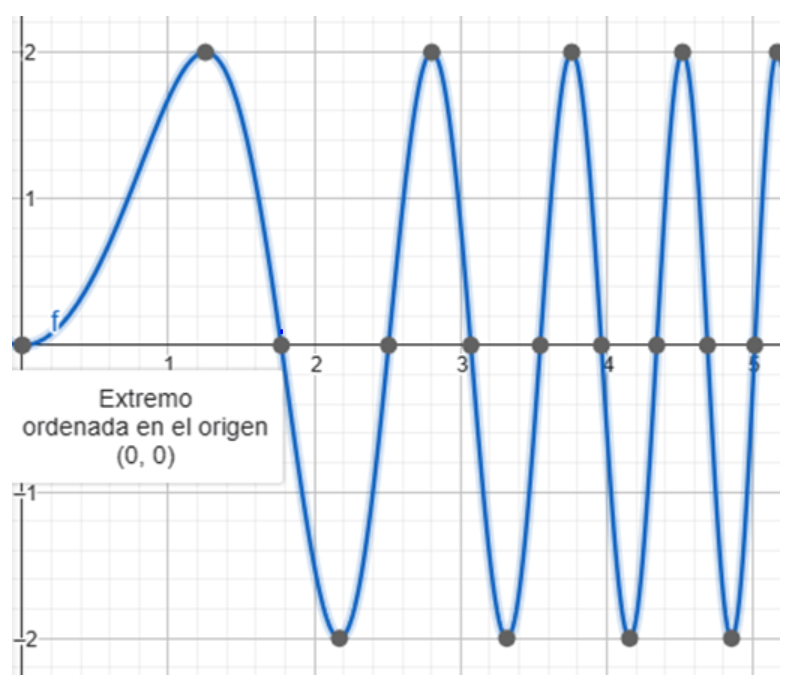

Para la primera parte tendremos esta onda senoidal por cuestiones de tiempo y sobre todo de que necesitamos tener mucho muestreo debido a que se buscan generar las ondas senoidales, tenemos que tener los arreglos concatenados pero con muchas muestras para poder generar un buen suavizado de las ondas y asi mostrar las ondas mas como una circunferencia.

- **PRIMERA PRUEBA CON SENO**

**Variables para el tiempo de simulación y muestreo, vector de tiempo y muestras**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 14             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

**Posición inicial robot**

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) = pi/4;   % Orientacion inicial del robot

**Velocidad lineal y angular**

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = ones(1,N);
w = sin(t).*ones(1,N); 

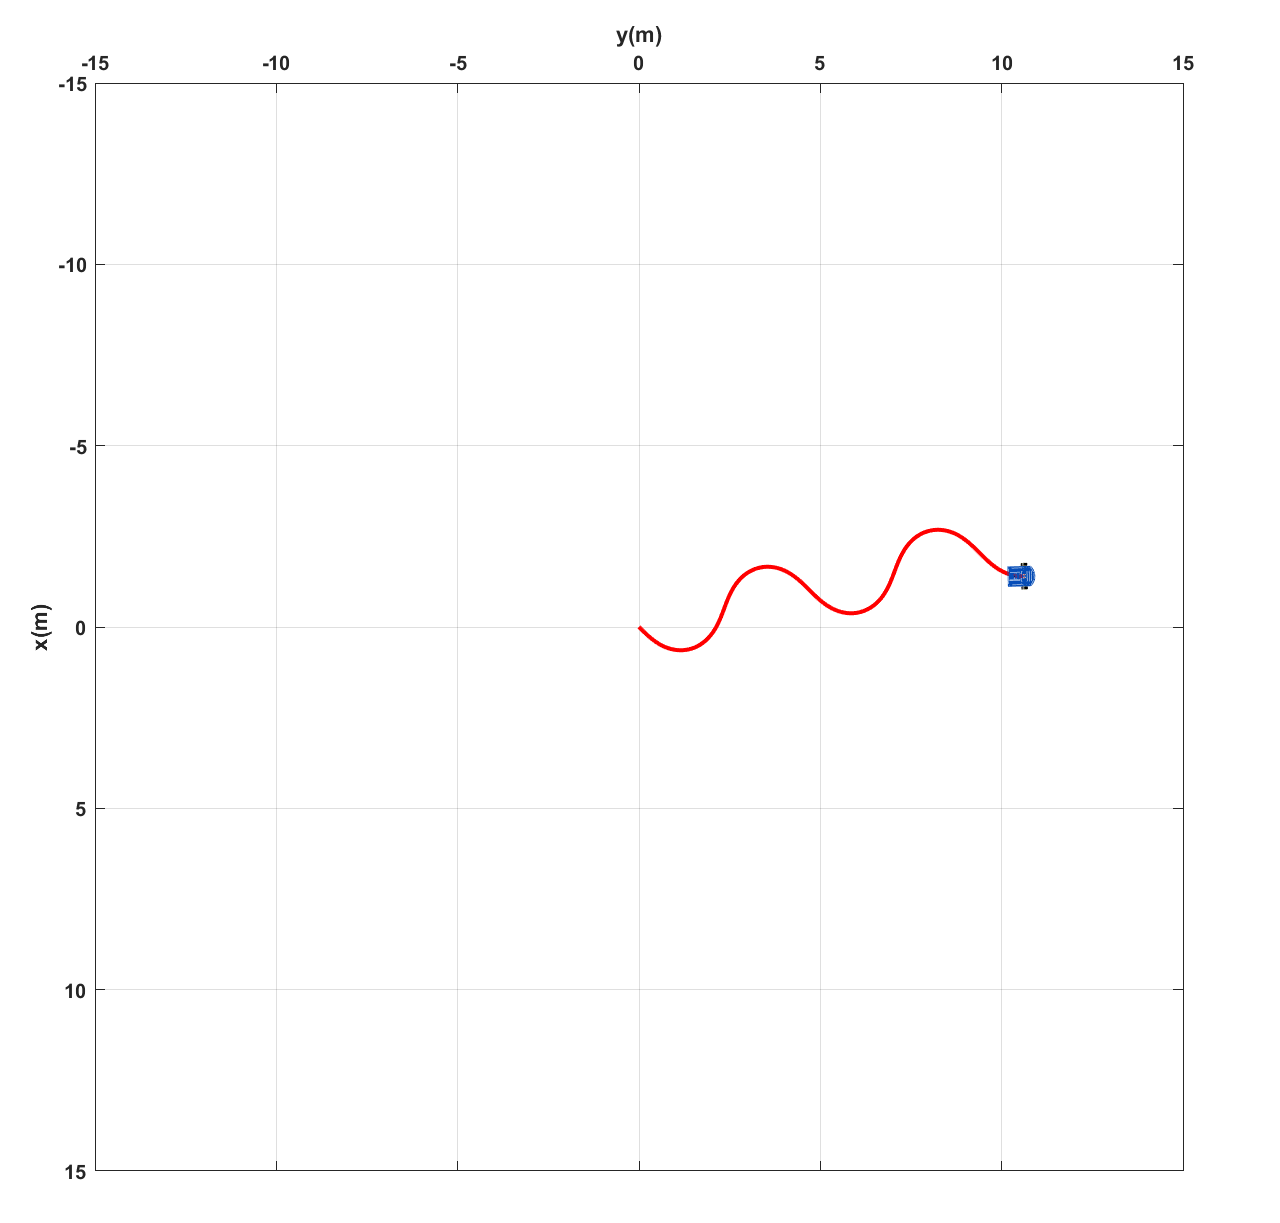

- **SEGUNDA PRUEBA CON PICOS**

**Variables para el tiempo de simulación y muestreo, vector de tiempo y muestras**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 14;             % Tiempo de simulacion en segundos (s)
ts = 1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

**Posición inicial robot**

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

**Velocidad lineal y angular**

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = [ 0  , 2.33,       0 ,  4.60,       0,      4.12,      0 ,    4.12,     0,   4.12,     0, 4.12,0, 4.12,0, 0]; % Velocidad lineal de referencia (m/s)
w = [pi/3,  0  ,  4*pi/3 ,  0   ,  3*pi/4,         0,  7*pi/6,       0, 3*pi/4,   0,  7*pi/6, 0, 3*pi/4, 0, 7*pi/6,   0]; % Velocidad angular de referencia (rad/s)

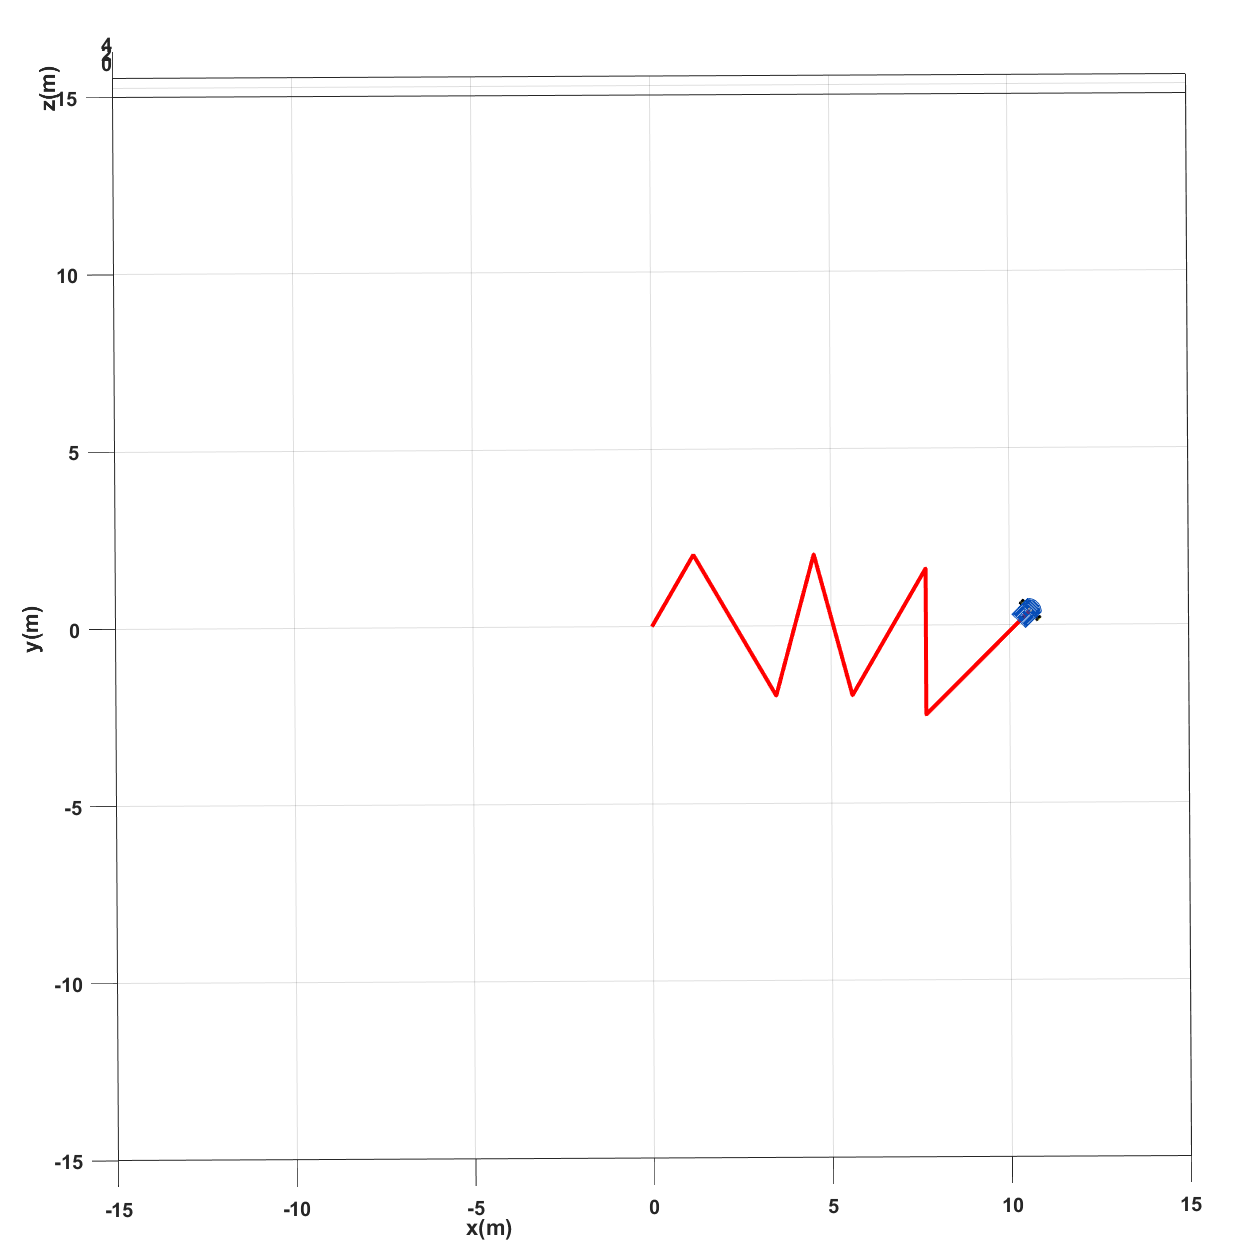

- **Segunda trayectoria**

**X = [-4 a 4]**

**F(x) = x^2 + y^2 - 16**

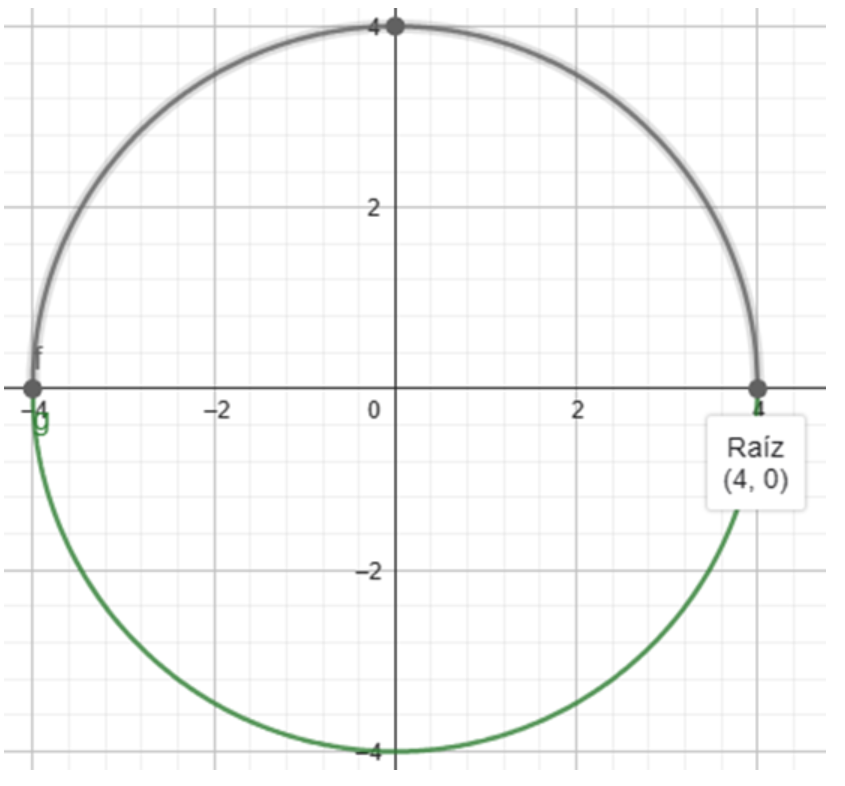

Para la segunda trayectoria vamos a observar que tenemos un circulo el cual tiene un radio de 4 por lo que es la primera consideracion que tomaremos en cuenta, además de que también es de -4 a 4 en el eje x y en el eje y. 

**Variables para el tiempo de simulación y muestreo, vector de tiempo y muestras**

Continuando vamos a proceder a definir los parámetros que se cambiaron en el archivo Main para poder hacer toda la trayectoria, teniendo primero un tiempo de simulación de 6.3 segundos debido a que como observamos en la simulación y pudiendo probar diferentes tiempos, con este de 6.3 segundos se pudo formar el circulo completo ya que para cada cuarto del circulo se tiene un estimado de 1.6 segundos y un tiempo de muestreo de 0.1 segundos para que haga el trazado del circulo de forma en que tengan muchas muestras para formar la circunferencia debido a que si tenemos un tiempo de muestreo más alto hay menos muestras y se puede formar un poligono que tenga lados como un hexagono.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 6.3;             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

**Posición inicial robot**

Para la posición inicial vamos a tomar en cuenta que debe de estar primeramente como ya sabemos en el eje y de -4 para que pueda hacer la circunferencia correctamente de 8 cm y también en el eje x tendriamos 0 pero en este caso por temas de que estuve probando como funcionaba y para hacerlo más exacto tenia un pequeño error, por lo que puse 0.2 para que se mantuviera dentro del diametro de -4 a 4 y se trazara más correcto y con mayor precision. Finalmente para la orientación del robot tendremos que es de 0 porque tomaremos como referencia la que ya esta por default para poder seguir la trayectoria del círculo.

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0.2;    % Posicion inicial eje x
y1(1) = -4;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

**Velocidad lineal y angular**

Como parte final del código, lo último que cambiamos fue las velocidades lineales y angulares, por lo que teniendo como primero vamos a inferir que se multiplicara por 4 la velocidad lineal para poder considerar el radio de 4 del circulo y tendremos un vector de unos para la velocidad angular teniendo las dos velocidades constantes pero con la lineal en 4 para hacer todo el recorrido tomando en cuenta el radio del circulo.

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = 4*ones(1,N);
w = ones(1,N); 

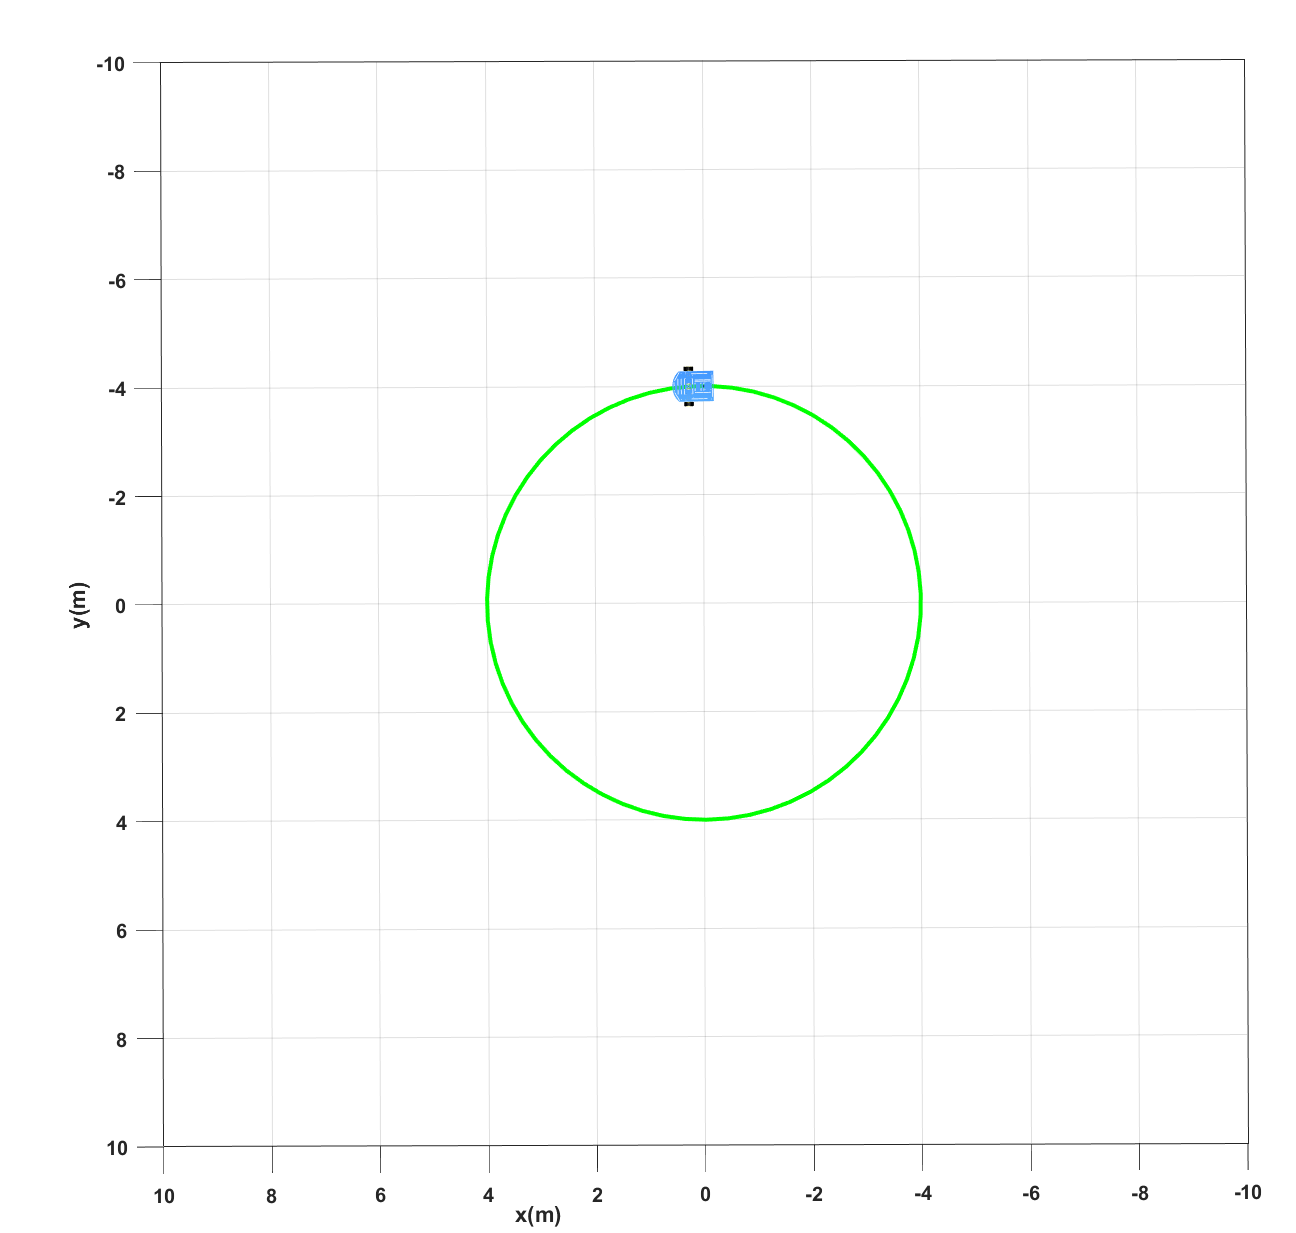

Podemos observar que correctamente se efectua la trayectoria con la consideración del radio de 4 para el circulo y tomando tambien en cuenta que va de -4 a 4 que se considera en la posición inicial del robot para lograr el trazado correctamente.

- **Gráficas de las velocidades lineales y angulares**

Primeramente la gráfica de u que es la velocidad lineal donde observamos que tenemos una línea recta en 4 en el eje y que va a indicar la velocidad lineal que es constante en 4 m/s durante todo el tiempo de la simulación lo que hace que concuerde con la definición de u como un vector constante de 4 que indicamos como el radio de nuestro circulo.

De la misma manera tendremos la grafica de w que es la velocidad angular donde se puede ver tambien reflejada una constante pero ahora en 1 m/s ya que no tendremos ningun cambio para la angular y además de que no tenemos ninguna multiplicación con el vector de unos por lo que se considera como constante en 1, al tener las dos constantes lograremos que se traze el circulo de buena manera pero con el valor que nosotros multipliquemos en la velocidad lineal sera el tamaño del radio que se le este dando para nuestra figura del circulo.

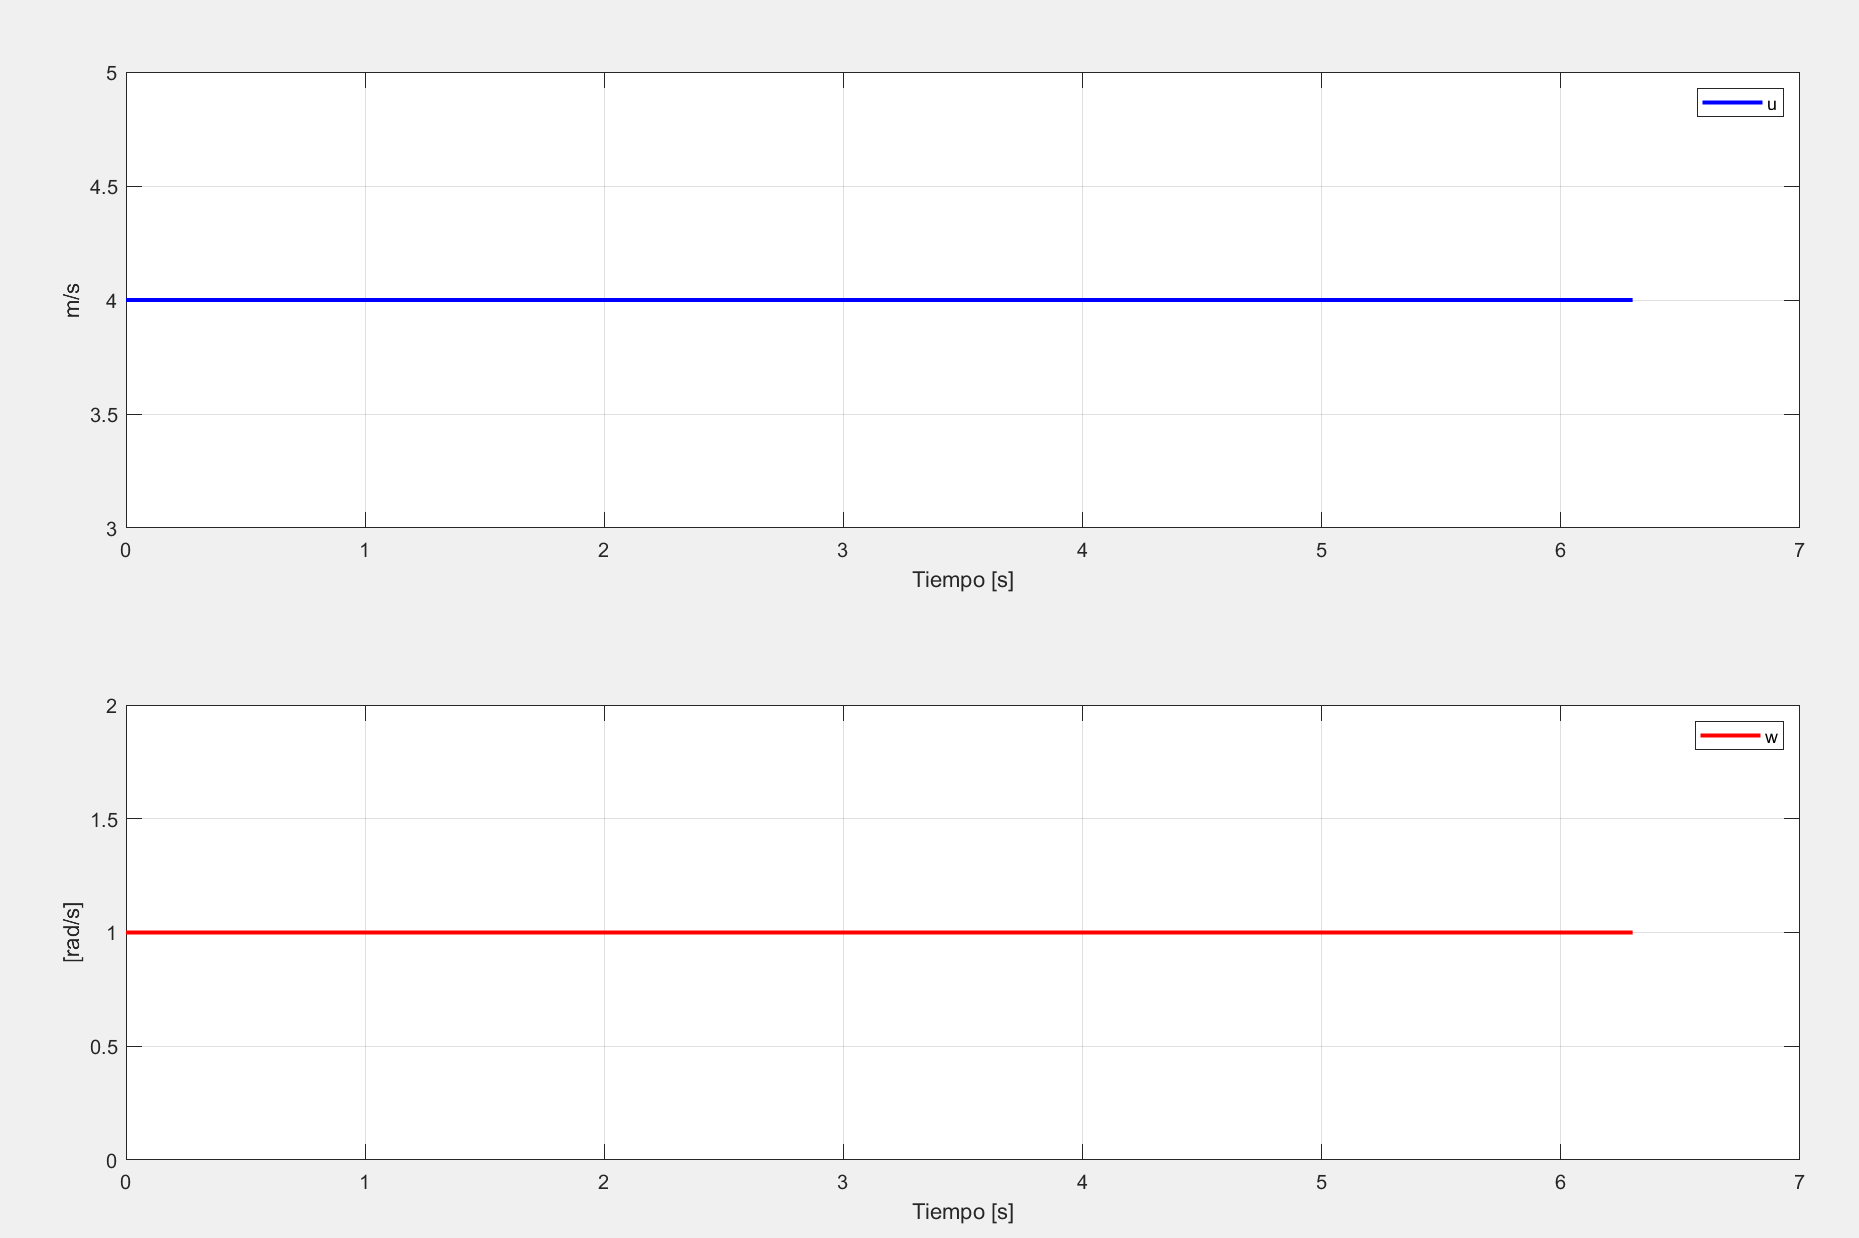

- **Tercera trayectoria**

**X = [-6 a 6]**

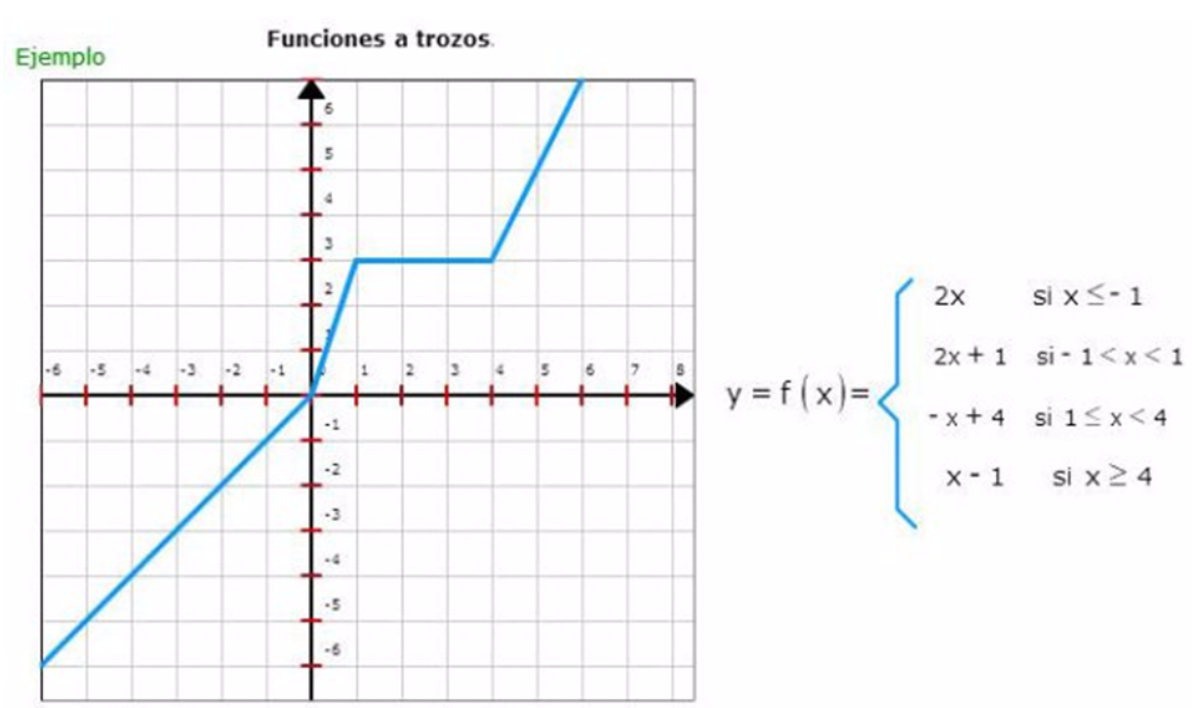

Para esta ultima trayectoria vamos a poder observar que va a ser una grafica donde tendremos que definir varios giros y tambien dezplazamiento del robot como las velocidades lineales y angulares por lo que hay que considerar cada movimiento que se haga del robot para el muestreo

**Variables para el tiempo de simulación y muestreo, vector de tiempo y muestras**

Con lo anteriormente definido podemos decir que en mi caso voy a considerar 7 movimientos para que el robot efectue la trayectoria completa sobre todo porque primeramente estare efectuando los giros en la velocidad angular y posteriormente el avance del robot en la velocidad lineal. Tambien un tiempo de muestreo de 1 segundo que va a indicar que cada parte de la simulación osea los movimientos los tiene que efectuar en 1 segundo sobre todo para tener un buen movimiento y trazar bien la trayectoria de cada parte sin que tenga perturbaciones o desalineaciones.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 7;             % Tiempo de simulacion en segundos (s)
ts = 1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

**Posición inicial robot**

Comenzando de la parte de la gráfica que podemos ver que empieza desde la parte inferior izquierda tendremos la posicion inicial del robot que declararemos como las coordenadas (-6,6) lo que puede tenerse como que desde ahi empezara su recorrido. Y con un angulo de pi/4 para poder tener ya la rotacion del robot como deberia de estar para poder comenzar a efectuar los movimientos de las velocidades lineales y angulares.

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = -6;    % Posicion inicial eje x
y1(1) = -6;   % Posicion inicial eje y
phi(1) = pi/4;   % Orientacion inicial del robot

**Velocidad lineal y angular**

Ahora continuaremos con la declaracion de las velocidades lo que vamos a explicar como los movimientos que hara el robot en cada parte:

**1. **Avanzar 8.5 unidades (velocidad lineal) y no tiene rotación (velocidad angular)

**2.** No avanza (velocidad lineal) y tiene rotación de 0.65 unidades (velocidad angular)

**3. **Avanzar 3 unidades (velocidad lineal) y no tiene rotación (velocidad angular)

**4. **No avanza (velocidad lineal) y tiene rotación negativa de -1.43 (velocidad angular)

**5. **Avanzar 3.6 unidades (velocidad lineal) y no tiene rotación (velocidad angular)

**6. **No avanza (velocidad lineal) y tiene rotación de 0.972 unidades (velocidad angular)

**7. **Avanza finalemente 3.8 unidades (velocidad lineal) y no tiene rotación debido a que termina el recorrido (velocidad angular)

**8. **Finalemente tendremos que declarar un 0 en las velocidades lineales y angulares debido que si no tenemos declarado un movimiento siguiente no puede efectuar el anterior es por ello que lo ponemos como 0, al final de cuentas esto no va a afectar para el trazado de la trayectoria.

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = [8.5,    0,  3,      0,  3.6,      0,  3.8,  0];
w = [0,   0.65,  0,  -1.43,    0,  0.972,    0,  0];

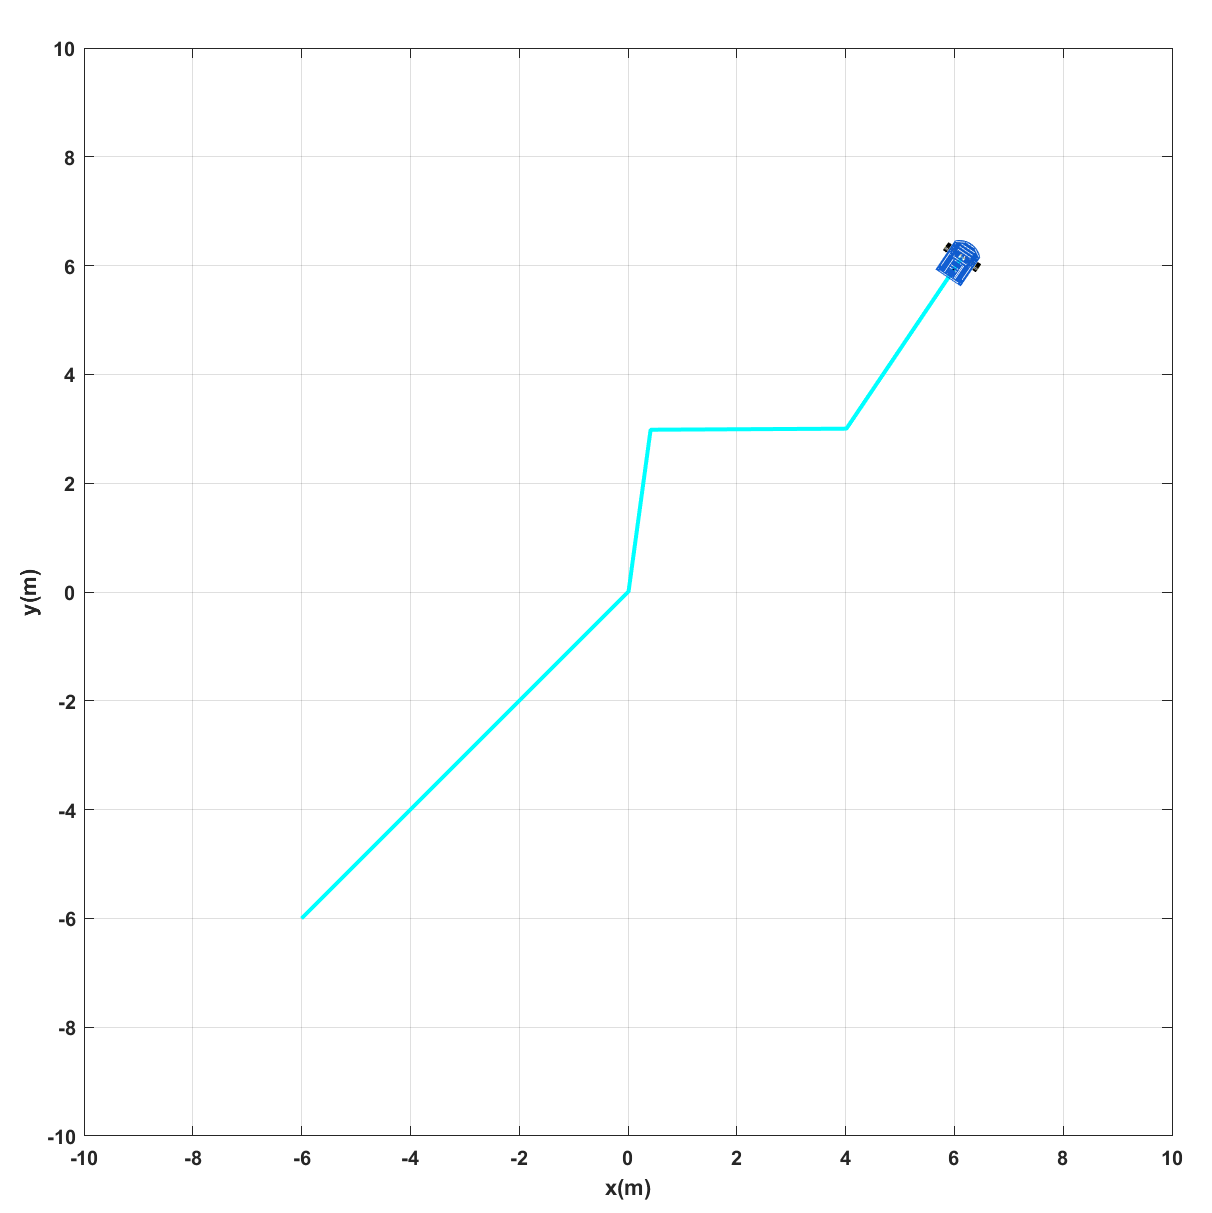

- **Gráficas de las velocidades lineales y angulares**

Ahora para las gráficas tendremos que para la lineal se pueden observar los picos que va a ser la desaceleración del robot por lo que tendremos una velocidad que va a alcanzar y bajando a 0 debido a que en esos instantes de tiempo se tiene un 0 para la lineal pero si representara que a continuación vuelva a tener una velocidad nuevamente y asi consecutivamente dependiendo de la cantidad de movimientos declarados.

Para la grafica de la velocidad angular tendremos lo mismo expresado pero ahora con el angulo dependiendo de como se ve el angulo y que tan grande es la rotacion que hace o que tan pequeño es el angulo para poder hacer la rotacion correspondiente, en la parte de los 0 es cuando tenemos el avance del robot para despues efectuar nuevamente un giro que se representa como esa caida y luego esa subida de la magnitud del angulo.